# Forward Difference Method

## En liten test

Tester først mot eksempelet i boka:

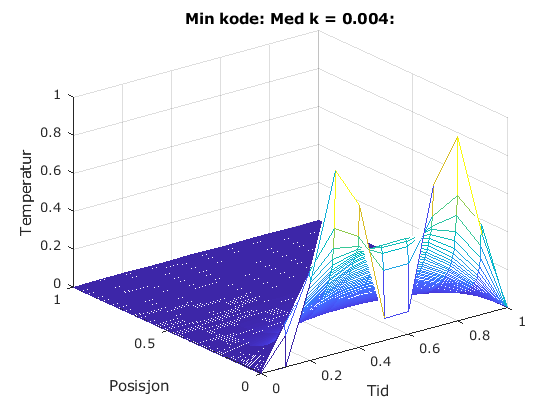

D = 1; M = 10; N = 250;
f = @(x) sin(2*pi*x).^2;
l = @(t) 0*t;
r = @(t) 0*t;
heatfdm(0, 1, 1, M, N, D, f, l, r);
title("Min kode: Med k = 0.004:");

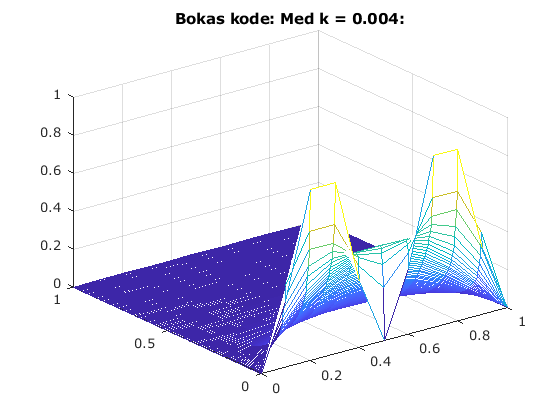

boka(0, 1, 0, 1, M, N, 1, f, l, r);
title("Bokas kode: Med k = 0.004:");

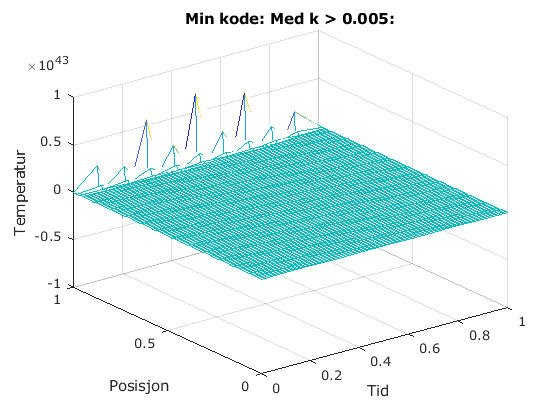

heatfdm(0, 1, 1, M, (1/0.01)-1, D, f, l, r);
title("Min kode: Med k > 0.005:");

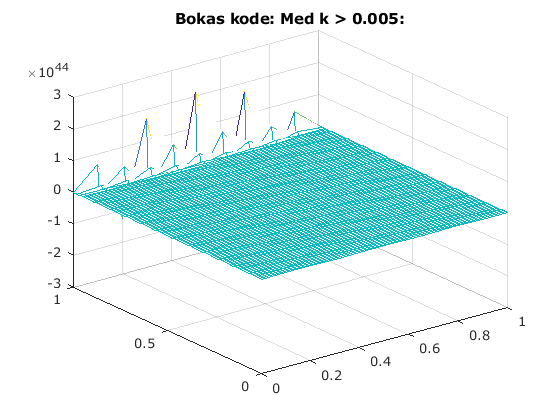

boka(0, 1, 0, 1, M, (1/0.01)-1, 1, f, l, r);
title("Bokas kode: Med k > 0.005:");

## CP1 – fellestrekk

Skal løse $u_t = 2u_{xx}
$ i begge deloppgavene – altså er $D=2
$.

D = 2;

Beregningene skjer med h = 0.1 og k = 0.002, altså M = 10 og N = 500.

M = 1/0.1;
N = 1/0.002;

Vi skal sammenligne med k > 0.003:

N2 = round(1/0.003) - 1;

## CP1a


$$u(x,0) = 2\cosh x \text{ for } 0 \le  x \le  1\\
u(0,t) = 2e^{2t} \text{ for } 0 \le  t \le  1\\
u(1,t) = (e^2 + 1)e^{2t-1} \text{ for } 0 \le  t \le  1$$


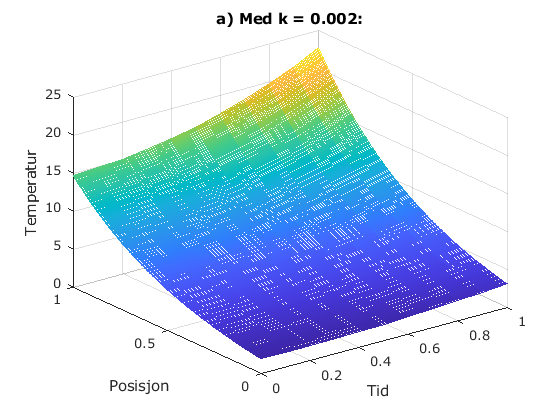

f = @(x) 2*cosh(x);
l = @(t) 2*exp(2*t);
r = @(t) (exp(2)+1)*exp(2*t-1);
heatfdm(0, 1, 1, M, N, D, f, l, r);
title("a) Med k = 0.002:");

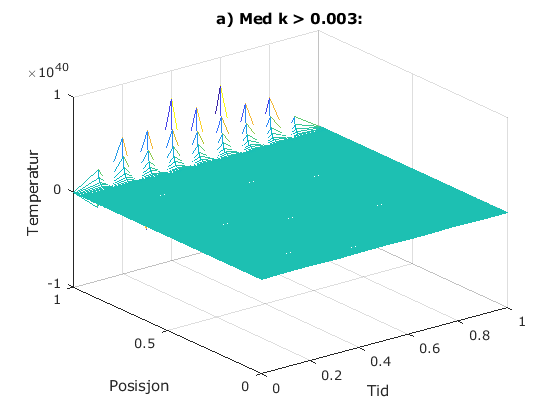

heatfdm(0, 1, 1, M, N2, D, f, l, r);
title("a) Med k > 0.003:");

## CP1b


$$u(x,0) = e^x \text{ for } 0 \le  x \le  1\\
u(0,t) = e^{2t} \text{ for } 0 \le  t \le  1\\
u(1,t) = e^{2t-1} \text{ for } 0 \le  t \le  1$$


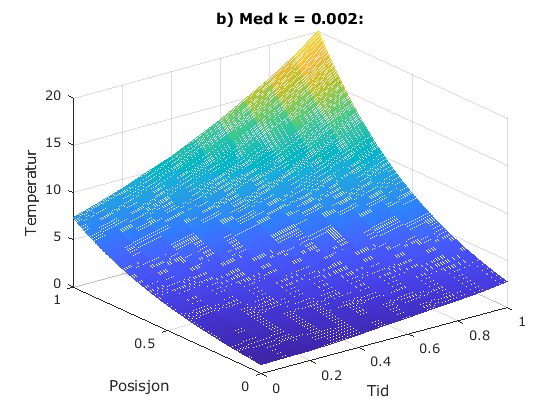

f = @(x) exp(x);
l = @(t) exp(2*t);
r = @(t) exp(2*t+1);
heatfdm(0, 1, 1, M, N, D, f, l, r);
title("b) Med k = 0.002:");

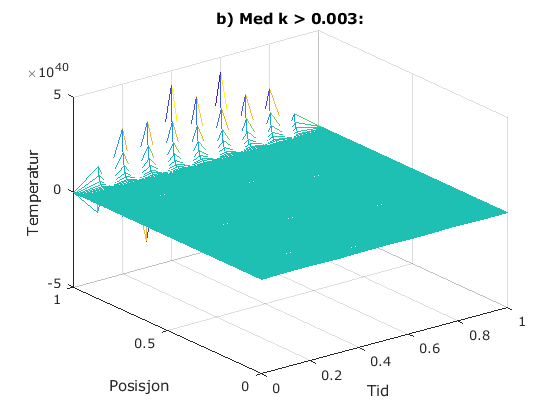

heatfdm(0, 1, 1, M, N2, D, f, l, r);
title("b) Med k > 0.003:");

Funksjonene:

function w=heatfdm(a, b, T, M, N, D, f, l, r)
%HEATBDM Forward Difference Method for the heat equation
%   Løser  u_t = D u_xx  numerisk
%   a og b er grensebetingelsene u(a,t)=l(t) og u(b,t)=r(t)
%   T utgjør høyre grense i tidsintervallet [0,T]
%   f(x) er initialbetingelsen for u(x,0)
%   D er diffusjonskoeffisienten (i den originale likningen)
%   M og N er antall samplinger langs x- og t-aksen
%   NB: f, l og r er funksjoner

    % Beregner steglengder og sigma
    h = (b-a)/M;
    k = T/N;
    sigma = D*k / (h*h);
    m = M-1;
    
    % Setter opp aksene
    x = linspace(a,b,M)';
    t = linspace(0,T,N+1);
    
    % Lager diagonalmatrisen A
    e = ones(m, 1);
    A = spdiags([sigma*e, (1-2*sigma)*e, sigma*e], [-1,0,1], m, m);

    w = zeros(m,N);
    %w(1,1:N) = l(t); % uh oh - l er ikke en funksjon i x
    %w(N,1:N) = r(t);
    w(:,1) = f(x(1:m));
    for i = 1:N
        s = sigma*[l(i*k) zeros(1,m-2) r(i*k)]';
        w(:,i+1) = (A*w(:,i) + s);
    end
    
    w = [l(t); w; r(t)];

    [X,T] = meshgrid(linspace(a,b,M+1)',t);
    mesh(X,T,w')
    xlabel('Tid')
    ylabel('Posisjon')
    zlabel('Temperatur')
end

function w=boka(xl,xr,yb,yt,M,N,D,f,l,r)
% Dette er kode fra boka, limt inn for å ha noe å sammenligne med
% etter å ha gjort et forsøk.
%
% Program 8.1 Forward difference method for heat equation
% input: space interval [xl,xr], time interval [yb,yt],
%number of space steps M, number of time steps N
% output: solution w
% Example usage: w=heatfd(0,1,0,1,10,250)
% diffusion coefficient
h=(xr-xl)/M; k=(yt-yb)/N; m=M-1; n=N;
sigma=D*k/(h*h);
a=diag(1-2*sigma*ones(m,1))+diag(sigma*ones(m-1,1),1);
a=a+diag(sigma*ones(m-1,1),-1);
% define matrix a
lside=l(yb+(0:n)*k); rside=r(yb+(0:n)*k);
w(:,1)=f(xl+(1:m)*h)';
% initial conditions
for j=1:n
w(:,j+1)=a*w(:,j)+sigma*[lside(j);zeros(m-2,1);rside(j)];
end
w=[lside;w;rside];
% attach boundary conds
x=(0:m+1)*h;t=(0:n)*k;
mesh(x,t,w')
% 3-D plot of solution w
%view(60,30);axis([xl xr yb yt -1 1])
end